# Descending Schlogl 

clear all
lattice_edge = 2; 
model_name = 'Schlogl_1_'+string(lattice_edge)

model_name = "Schlogl_1_2"


%rate constants
kdif = 0.15;    %diffusion
r01 = 6;    
r10 = 11;
r23 = 6;
r32 = 1;

Schlogl_1D_lattice
plotnam = string(lattice_edge)+"-Schlogl"

plotnam = "2-Schlogl"

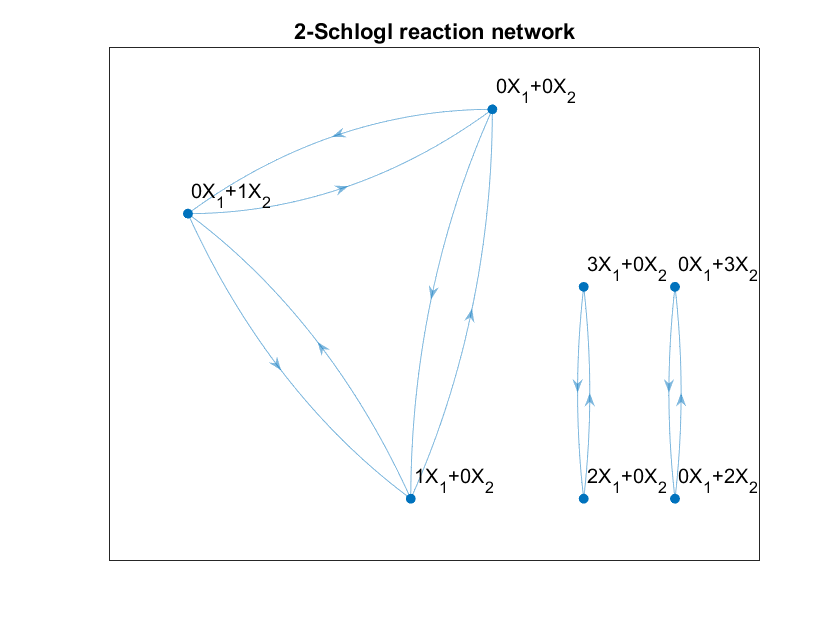

Hypergraph_plotter

G = digraph();
G_model = Hypergraph_plotter(G,comp_vec_name,rxn_rate,plotnam);

[mf,GF,cs,ct]  = maxflow(G_model,comp_vec_name(1),comp_vec_name(2))

mf = 6.1500

GF =   digraph with properties:

    Edges: [3×2 table]
    Nodes: [7×1 table]


cs = 2×1 string array
    "0X_1+0X_2"
    "0X_1+1X_2"


ct = 5×1 string array
    "1X_1+0X_2"
    "2X_1+0X_2"
    "3X_1+0X_2"
    "0X_1+2X_2"
    "0X_1+3X_2"


(*This is cool. Maxflow - mincut *)

Splus = comp_vec(rxn_rate(:,2),:)

Splus =      1     0
     0     0
     3     0
     2     0
     0     1
     0     0
     0     3
     0     2
     0     1
     1     0


Smin = comp_vec(rxn_rate(:,1),:)

Smin =      0     0
     1     0
     2     0
     3     0
     0     0
     0     1
     0     2
     0     3
     1     0
     0     1


$$Slamk = \left(\begin{array}{cc} 1 & 0\\ -\lambda & 0\\ 3-2\,\lambda & 0\\ 2-3\,\lambda & 0\\ 0 & 1\\ 0 & -\lambda \\ 0 & 3-2\,\lambda \\ 0 & 2-3\,\lambda \\ -\lambda & 1\\ 1 & -\lambda \end{array}\right)$$

num_rxn = 10

$$ans = \left(\begin{array}{cc} K_{1} & 0\\ -K_{2}\,\lambda & 0\\ -K_{3}\,\left(2\,\lambda -3\right) & 0\\ -K_{4}\,\left(3\,\lambda -2\right) & 0\\ 0 & K_{5}\\ 0 & -K_{6}\,\lambda \\ 0 & -K_{7}\,\left(2\,\lambda -3\right)\\ 0 & -K_{8}\,\left(3\,\lambda -2\right)\\ -K_{9}\,\lambda & K_{9}\\ K_{10} & -K_{10}\,\lambda \end{array}\right)$$

sol = struct with fields:
        K1: [3×1 sym]
        K2: [3×1 sym]
        K3: [3×1 sym]
        K4: [3×1 sym]
        K5: [3×1 sym]
        K6: [3×1 sym]
        K7: [3×1 sym]
        K8: [3×1 sym]
        K9: [3×1 sym]
       K10: [3×1 sym]
    lambda: [3×1 sym]


$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ \frac{3}{2}\\ \frac{2}{3} \end{array}\right)$$

Splus =      0     2     0
     1     0     0
     0     1     0


Smin =      1     0     0
     0     1     0
     0     0     1


$$Slamk = \left(\begin{array}{ccc} -\lambda & 2 & 0\\ 1 & -\lambda & 0\\ 0 & 1 & -\lambda \end{array}\right)$$

num_rxn = 3

$$K = \left(\begin{array}{c} K_{1}\\ K_{2}\\ K_{3} \end{array}\right)$$

$$null\_flow = \left(\begin{array}{c} 2\,K_{2}-K_{1}\,\lambda \\ K_{1}-K_{2}\,\lambda \\ K_{2}-K_{3}\,\lambda \end{array}\right)$$

sol = struct with fields:
        K1: [3×1 sym]
        K2: [3×1 sym]
    lambda: [3×1 sym]


$$ans = \left(\begin{array}{c} 0\\ 2\,K_{3}\\ 2\,K_{3} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ \sqrt{2}\,K_{3}\\ -\sqrt{2}\,K_{3} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ \sqrt{2}\\ -\sqrt{2} \end{array}\right)$$

rxn_rate
comp_vec_name

rxn_rate =     1.0000    2.0000    6.0000
    2.0000    1.0000   11.0000
    3.0000    4.0000    6.0000
    4.0000    3.0000    1.0000
    1.0000    5.0000    6.0000
    5.0000    1.0000   11.0000
    6.0000    7.0000    6.0000
    7.0000    6.0000    1.0000
    2.0000    5.0000    0.1500
    5.0000    2.0000    0.1500


comp_vec_name = 7×1 string array
    "0X_1+0X_2"
    "1X_1+0X_2"
    "2X_1+0X_2"
    "3X_1+0X_2"
    "0X_1+1X_2"
    "0X_1+2X_2"
    "0X_1+3X_2"
